% Main body of shuttle
x = linspace(0,6,20);
y = sqrt(9 - ((x-3).^2))+4;
X = [x 6 0 0;x 6 0 0];
Y = [abs(y) 0 0 4;abs(y) 0 0 4];
Z = [zeros(1,23); 30*ones(1,23)]; 
surf_handle1 = surf(X,Y,Z)

surf_handle1 =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×23 double]
           YData: [2×23 double]
           ZData: [2×23 double]
           CData: [2×23 double]

  Show all properties


set(surf_handle1,'linestyle','none','FaceColor',[0.9 0.9 0.9])
patch([x 6 0 0],[abs(y) 0 0 4],[zeros(1,23)],'white')
axis equal  
hold on
x1 = [linspace(1.5,4.5,20) linspace(4.5,1.5,20)];
xa = linspace(1.5,4.5,20);
xb = linspace(4.5,1.5,20);
y1 = [(sqrt(1.5^2 - (xa-3).^2)+2) -(sqrt(1.5^2 - (xb-3).^2)-2) ];
X1 = [x 6*ones(1,7) linspace(6,0,6) zeros(1,7);x1];
Y1 = [abs(y) linspace(4,0,6) zeros(1,8) linspace(0,4,6);y1];
Z1 = [30*ones(1,40);36*ones(1,40)];
surf_handle2 = surf(X1,Y1,Z1) 

surf_handle2 =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×40 double]
           YData: [2×40 double]
           ZData: [2×40 double]
           CData: [2×40 double]

  Show all properties


set(surf_handle2,'linestyle','none','FaceColor',[0.9 0.9 0.9])
axis equal


[X2,Y2,Z2] = sphere;      
X2 = X2(11:end,:);       
Y2 = Y2(11:end,:);    
Z2 = Z2(11:end,:);      
r = 1.5;              
surf_handle3 = surf(r.*X2+3,r.*Y2+2,r.*Z2+36); 
set(surf_handle3,'linestyle','none','FaceColor',[0.1 0.1 0.1])
axis equal; 
light

% Wings 
X3 = [6 8 14.5 14.5 8 6 6;6 8 14.5 14.5 8 6 6];
Y3 = [0 0 0 1 1 1 0;0 0 0 1 1 1 0];
Z3 = [0 0 0 0 0 0 0;30 15 3.5 3.5 15 30 30];
surf_handle4 = surf(X3,Y3,Z3);
set(surf_handle4,'linestyle','none','FaceColor',[0.9 0.9 0.9])

X4 = -(X3-6);
Y4 = [0 0 0 1 1 1 0;0 0 0 1 1 1 0];
Z4 = [0 0 0 0 0 0 0;30 15 3.5 3.5 15 30 30];
surf_handle5 = surf(X4,Y4,Z4);
set(surf_handle5,'linestyle','none','FaceColor',[0.9 0.9 0.9]) 

X5 = [6 8 14.5 14.5 8 6 6];
Y5 = [0 0 0 1 1 1 0];
Z5 = [30 15 3.5 3.5 15 30 30];
patch(X5,Y5,[0 0 0 0 0 0 0],'black')
patch(X5,Y5,Z5,'black')

X6 = [0 -2 -8.5 -8.5 -2 0 0];
Y6 = Y5;
Z6 = Z5;
patch(X6,Y6,Z6,'black') 
patch(X6,Y6,[0 0 0 0 0 0 0],'black') 

% Tail 
X7 = [2.5 2.5 3.5 3.5 2.5;2.5 2.5 3.5 3.5 2.5];
Y7 = [7 14.5 14.5 7 7;7 14.5 14.5 7 7];
Z7 = [0 -2 -2 0 0;10 2 2 10 10];
surf_handle7 = surf(X7,Y7,Z7);
set(surf_handle7,'linestyle','none','FaceColor',[0.9 0.9 0.9]) 
patch([2.5 2.5 3.5 3.5 2.5],[7 14.5 14.5 7 7],[0 -2 -2 0 0],'black')
patch([2.5 2.5 3.5 3.5 2.5],[7 14.5 14.5 7 7],[10 2 2 10 10],'black') 

%Engines
[X8,Y8,Z8] = cylinder([1.25,0.75])

X8 =     1.2500    1.1888    1.0113    0.7347    0.3863    0.0000   -0.3863   -0.7347   -1.0113   -1.1888   -1.2500   -1.1888   -1.0113   -0.7347   -0.3863   -0.0000    0.3863    0.7347    1.0113    1.1888    1.2500
    0.7500    0.7133    0.6068    0.4408    0.2318    0.0000   -0.2318   -0.4408   -0.6068   -0.7133   -0.7500   -0.7133   -0.6068   -0.4408   -0.2318   -0.0000    0.2318    0.4408    0.6068    0.7133    0.7500


Y8 =          0    0.3863    0.7347    1.0113    1.1888    1.2500    1.1888    1.0113    0.7347    0.3863    0.0000   -0.3863   -0.7347   -1.0113   -1.1888   -1.2500   -1.1888   -1.0113   -0.7347   -0.3863         0
         0    0.2318    0.4408    0.6068    0.7133    0.7500    0.7133    0.6068    0.4408    0.2318    0.0000   -0.2318   -0.4408   -0.6068   -0.7133   -0.7500   -0.7133   -0.6068   -0.4408   -0.2318         0


Z8 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


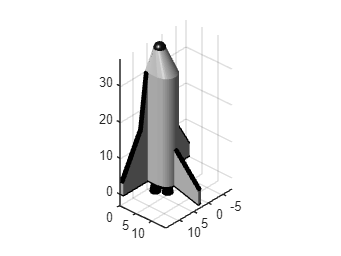

surf(X8+1.5,Y8+2,3*Z8-3,'FaceColor','black');
surf(X8+4.5,Y8+2,3*Z8-3,'FaceColor','black');
surf(X8+3,Y8+4.5,3*Z8-3,'FaceColor','black');